clc
clear all
close all
addpath("functions")



**1 GP complexity**

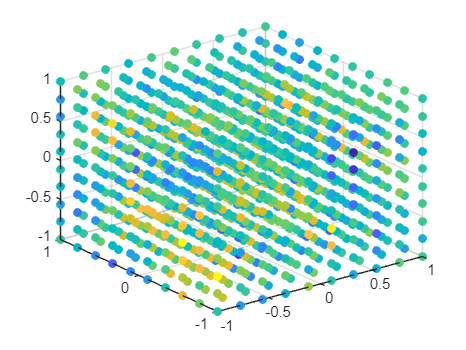

hyp = [0.05;1]; %defining hyper parameters
Nd = [10 15 20];

for i = 1:length(Nd)
    %generate dataset
    [X,y,Xstar] = getdata(Nd(i),hyp);
    if Nd(i) == 10
        X1 = X;
        y1 = y;
        Xstar1 = Xstar;
    end

    %Perform GP regression, time it and calculate the models mean and covariance for
    %new points and kernel matrix for training points.
    tic
    [GPmodel,predictions,mean, cov, k_matrix] = GPregression(X,y,Xstar,hyp);
    elapsed_time = toc;

    %Save relevantdata in results parameter.
    results.GPmodel = GPmodel;
    results.predictions = predictions;
    results.mean = mean;
    results.cov = cov;
    results.k_matrix = k_matrix;
    results.elapsed_time = elapsed_time;
    results.Nd = Nd(i);
    

    %allocate output of the model
    GP_data{i} = results;
end

%Getting predictions of model for Nd = 10
preds = GP_data{1}.predictions;
%First 3D scatterplot of data
scatter3(X1(:,1),X1(:,2),X1(:,3),[],y1,'filled')

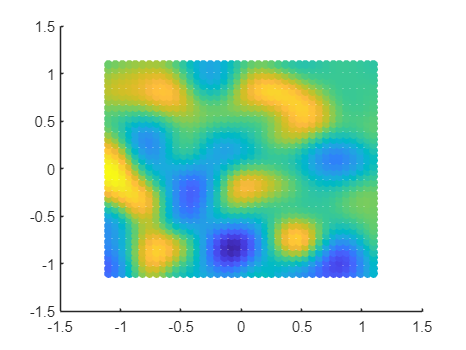

%Second 3D scatterplot of predictions
scatter(Xstar1(:,1),Xstar1(:,3),[],preds,'filled')


%Additional plots to understand the data
figure;
plot(y)
